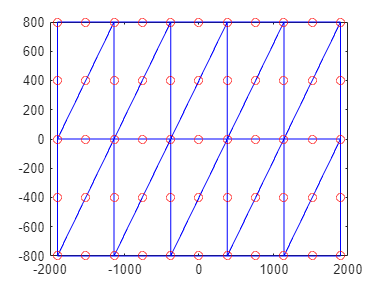

elementos_nome_ficheiro = "ELEMENTOS.txt";

nos_nome_ficheiro = "NOS.txt";

[x, y, tri6] = Gerar_Malha(elementos_nome_ficheiro, nos_nome_ficheiro);

visualisar_malha_simples(x, y, tri6)


[Kg, fg] = Assemblagem_Triangular_Quadratica(x, y, tri6);

fg = neumann(selecionar(x, -1900),fg,-2500)

fg =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



Kr = Kg;
fr = fg;

[Kr, fr] = dirichlet(selecionar(x, 1900), Kr, fr)

Kr = 1.0e+16 *

    0.0000         0    0.0000         0         0         0         0         0   -0.0000         0   -0.0000         0   -0.0000         0         0         0    0.0000         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0000         0    0.0000         0
         0    0.0000         0    0.0000         0         0         0         0         0   -0.0000         0   -0.0000         0   -0.0000         0         0         0    0.0000         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0000   

fr =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



u = Kr\fr;

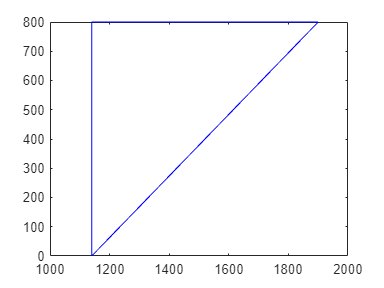

Unrecognized function or variable 'no1'.

Error in visualisar_malha_com_fluxos (line 42)
        um(i) = -(d1dx*u(no1)+d2dx*u(no2)+d3dx*u(no3));


visualisar_malha_com_fluxos(x, y, tri6, u)